# P06: Sistemas de inferencia difusos (FIS)

`2MM12 - Sistemas Nerodifusos - Marzo 2022`

**Integrantes**

- Carlos Daniel Domínguez Mota

- Daniel Castillo Carrillo

- David Vanegas García

- Jaqueline Tinoco Vázquez

- Marco Antonio Morán Caballero

## Objetivos

- Implementar sistemas de inferencia difusos, utilizando MATLAB

- Decodificar sistemas de inferencia difusos implementados en Simulink

## Introducción

Una de las principales características del modelo de inferencia difusa de Tsukamoto es que una línea recta que atraviesa todo el universo de las funciones de pertenencia a cualquier altura del eje vertical sólo puede cruzar la función una vez, es decir, no puede ser convexa, lo que se debe al método utilizado para la defuzzificación.

Ahora, para el procedimiento, el primer paso es la defuzzificación, donde se sustituyen los valores determinados en los conjuntos difusos de entrada. Una vez realizado este paso, el siguiente es evaluar las reglas "si...entonces", dando como resultado el peso, cuya nomenclatura habitual es w, y a partir de éste, z.

Por último, si se quiere generar la superficie de control del sistema, hay que evaluar todos los posibles valores de entrada para obtener la altura Z de la salida. 

### Problema 1

La herramienta **Fuzzy Logic Toolbox (FLT)**, Cuenta con una interfaz gráfica de diseño de sistemas de inferencia difusos

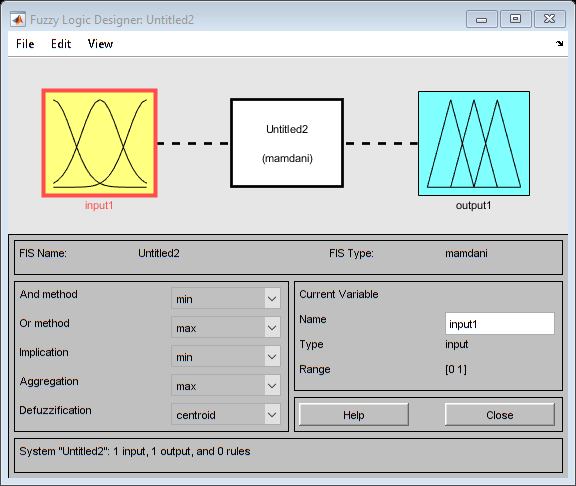

fuzzyLogicDesigner()

Para conocer el uso de esta interfaz se puede consultar la implementación del **problema de la propina** (problema de un sistema con dos entradas y una salida). La implementación es mediante la inferencia tipo Mamdani. Para consultar dicha implementación puedes revisar el siguiente enlace: [Build Fuzzy Systems Using Fuzzy Logic Designer](https://www.mathworks.com/help/fuzzy/building-systems-with-fuzzy-logic-toolbox-software.html)

El problema a desarrollar consiste en hacer uso de la herramienta gráfica para construir un sistema de inferencia difuso tipo Mamdani. El problema es una variante del problema de la propina. Las condiciones son las siguientes:

- 2 entradas (servicio y comida)

- El universo de discurso de ambas variables lingüisticas es $[0,100]$

- 1 salida (propina)

- El universo de discurso de esta variable lingúistica es [0,15] 

- Cada variable lingúistica debe tener por lo menos cuatro valores lingúisticos. Por lo menos un valor lingúistico debe ser una variación de un primitivo (por ejemplo: muy rica).

- La semántica de cada variable lingüistica se deja a su *"experiencia como consumidor"*

- Se tienen que proponer por lo menos cuatro reglas "si...entonces", para la inferencia difusa (se tiene que utilizar por lo menos una vez cada conjunto difuso propuesto en su semántica)

En el desarollo se espera el planteamiento del problema a resolver, así como documentar la construcción correspondiente (parecido a lo presentado en el enlace anterior).

Para esta variación del problema de la propina, se propone generar un FIS o sistema de inferencia difuso del tipo Mamdani, que cuente esta vez con 4 valores lingüisticos para cada variable, haciendo además uso de la variación de los valores lingüisticos primitivos, para ello, se llevan a cabo los pasos siguientes:

El primer paso consiste en asignar y nombrar cada una de las variables lingüisticas.

Posteriormente, se caracterizan las entradas y salidas de acuerdo con lo requerido, incluyendo rango, valores lingüisticos, y forma del conjunto difuso.

Por último, se establecen las reglas "Si...Entonces".

Finalmente se puede visualizar el resultado del sistema.

**Comenzamos colocando la expresion “fuzzyLogicDesigner()” en nuestra ventana de comandos para abrir la interfaz del Fuzzy Logic Designer (Figura 1).**

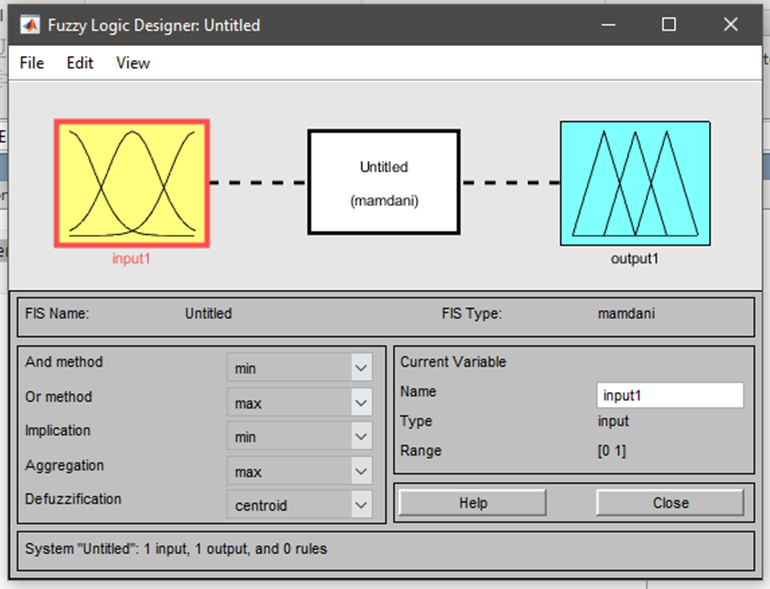

**Comenzamos colocando la expresion “fuzzyLogicDesigner()” en nuestra ventana de comandos para abrir la interfaz del Fuzzy Logic Designer (Figura 1).**

*Figura 1: Interfaz Fuzzy Logic Designer.*

**A continuacion agregamos una nueva entrada ya que para este sistema requerimos de dos enteadas(Figura 2).**

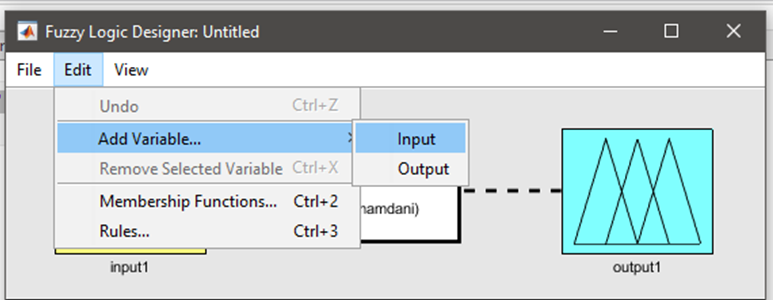

*Figura 2: Menu edit para agregar una nueva entrada.*

**Ahora procedemos a cambiar el nombre de las entradas, la salida y procedemos a exportarlo al workspace con el nombre “Probelma1”(Figura 3).**

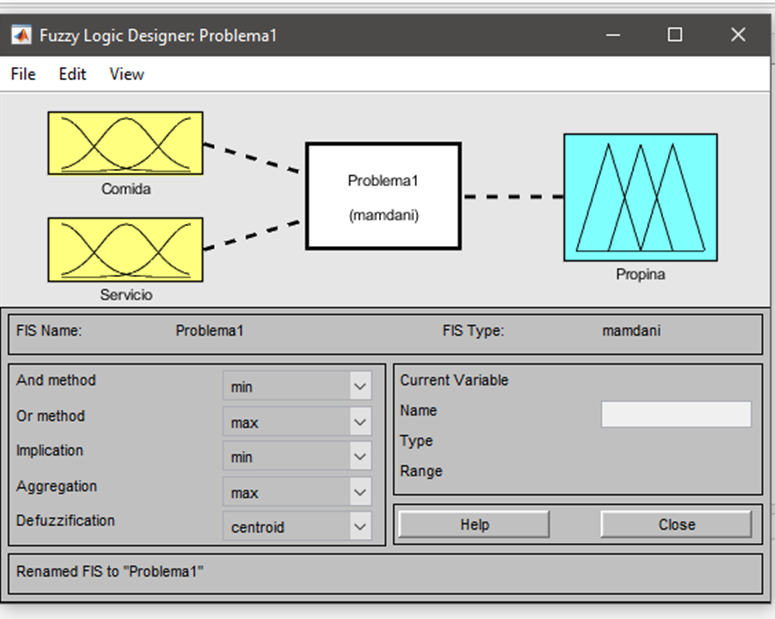

*Figura 3: Interfaz con los nombres cambiados.*

**El siguiente paso es dar doble click a la entrada “comida” para poder modificar sus propiedas. **

**Comenzaremos eliminando las funciones de membrecia definidas(Figura 4),para poder colocar las nuestras (Figura 5).**

 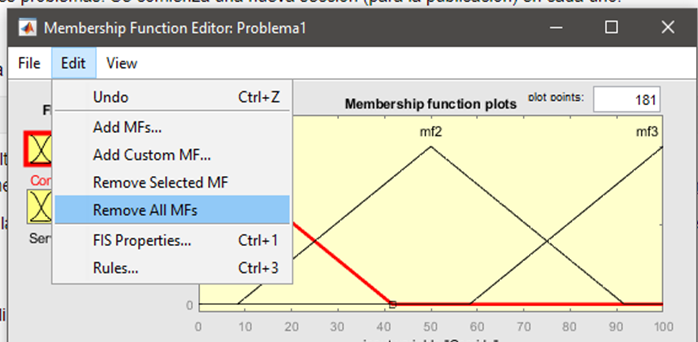       

*Figura 4: Borramos funciones de membrecía.*

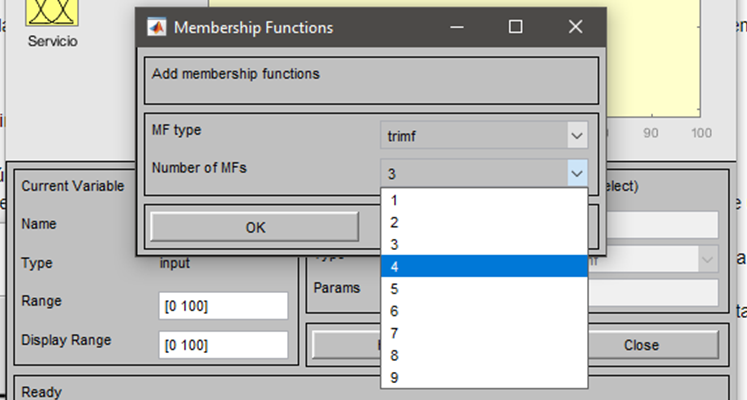

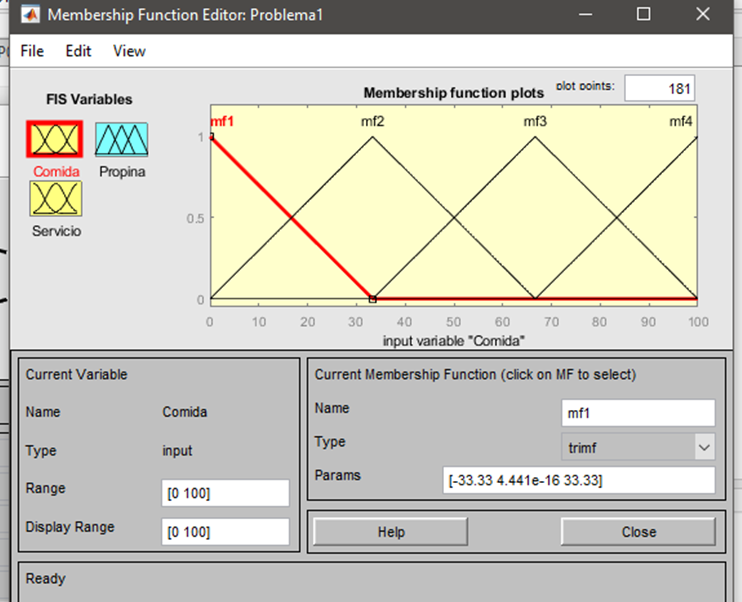

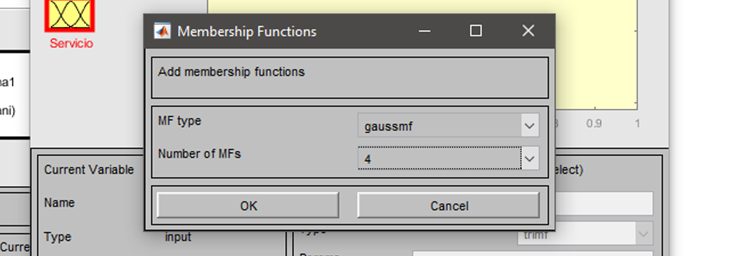

 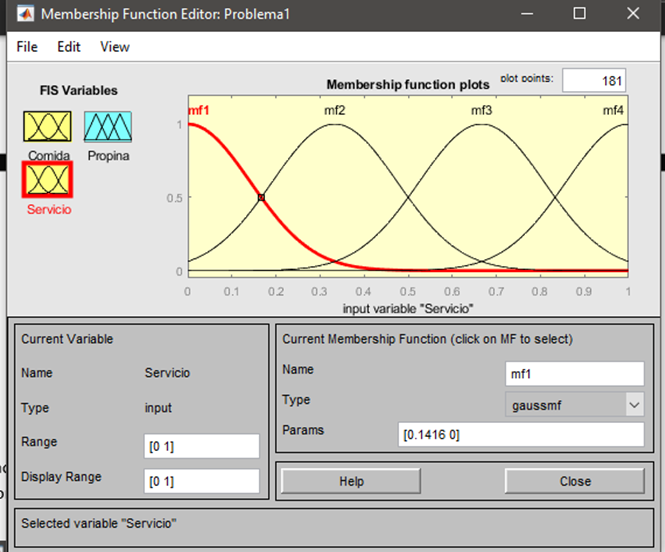

**Continuamos modificando las propiedade de la funcion de membrecia modificando el rango y los  valores linguisticos variables (Figura 6).**

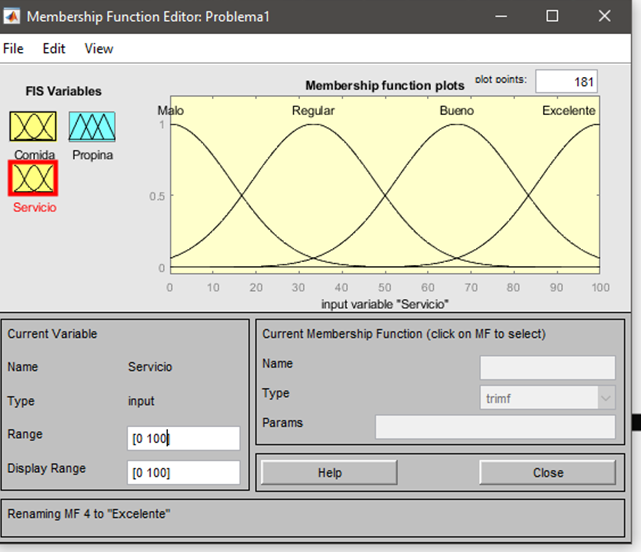

*Figura 6: Modificar funciones de membrecía*.

**Hacemos el mismo procedimiento que con las entradas, pero esta vez con la salida propina (Figura 7).**

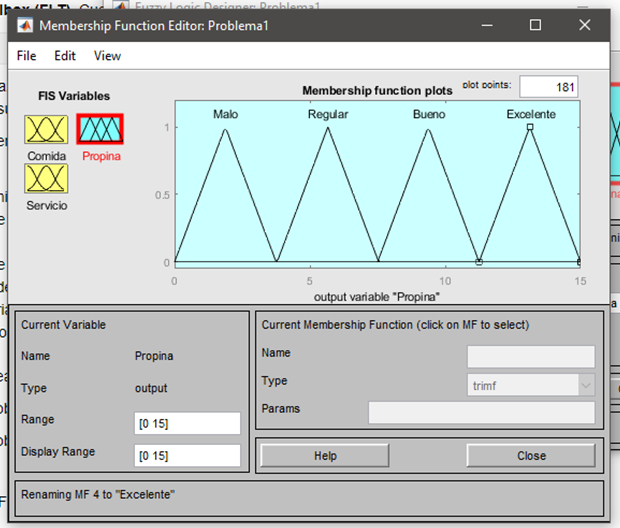

*Figura 7: Modificaciones de la salida “Propina”.*

**Ahora que nuestras entradas y salidas están completamente definidas, además de contar con funciones de membrecía y formas correctas, procederemos a crear las reglas del sistema. **

**Para ello primero debemos abrir el menú “rules” (Figura 8).**

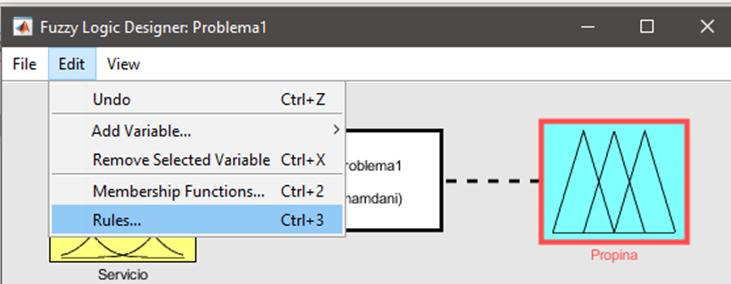

*Figura 8: Abrimos el menú “Rules”.*

**Finalmente Procedemos a agregar las reglas del sistema (Figura 9).**

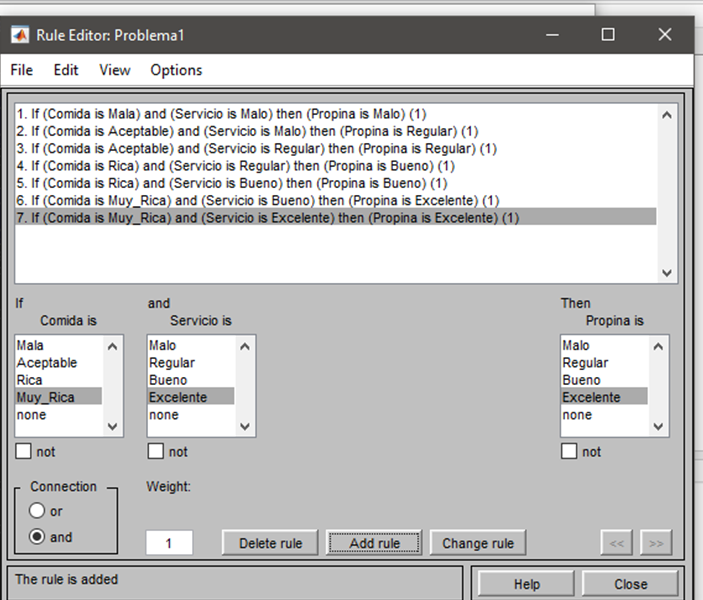

*Figura 9: Creamos las reglas del sistema.*

**Por último, veremos cómo funciona el sistema siguiendo las reglas en el sistema en el “Rule Viewer”(Figura 10, 11, 12 y 13)**

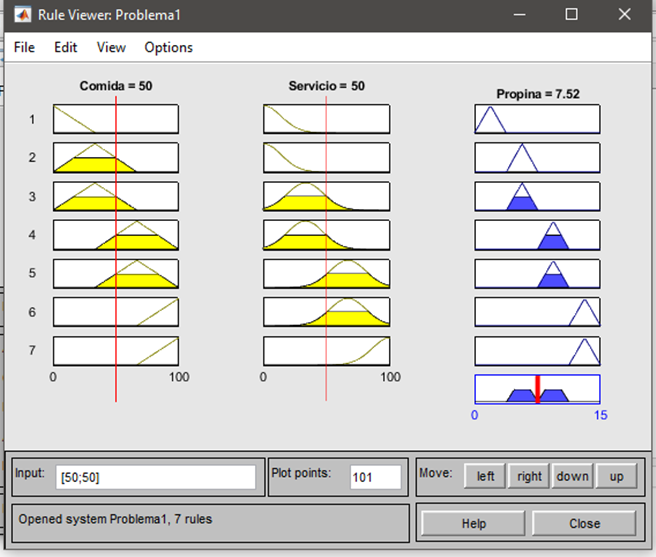

*Figura 10*

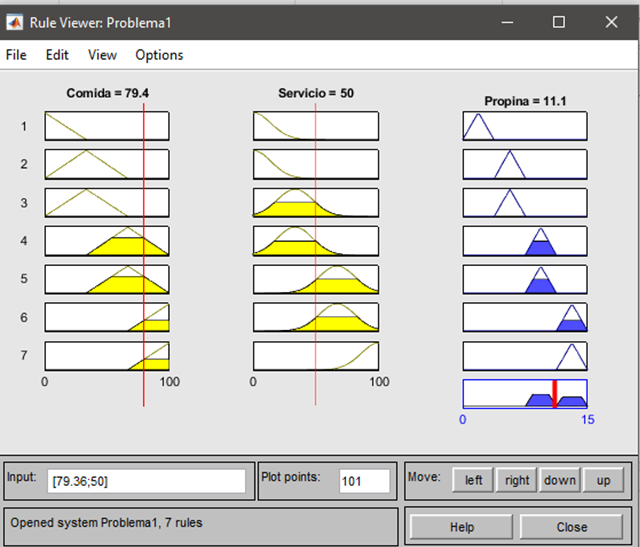

*Figura 11*

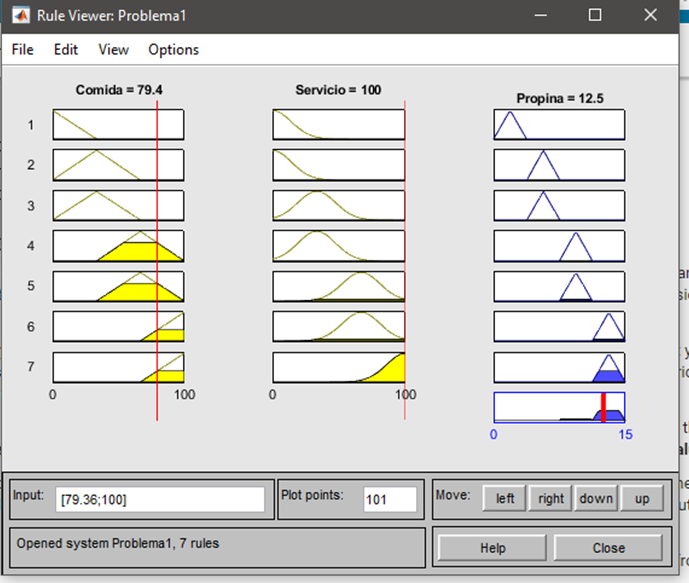

*Figura 12*

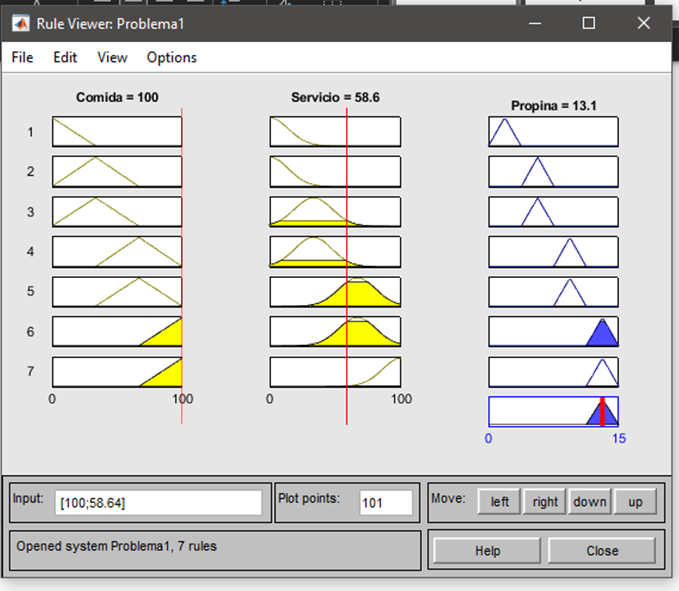

*Figura 13*

**       ¿Existe una situación donde el problema usual tenga "mal desempeño" al compararlo con tu implementación?**

En el caso de que se quieran usar una entrada donde no se definan bien los pesos de cada variable. 

**        ¿Existe una situación donde el problema usual tenga "mejor desempeño" al compararlo con tu implementación?**

Si se definen correctamente los datos de entrada donde se asignan los valores lingüísticos por cada variable, en este caso 4 por cada una.

### Problema 2

La impletación en Simulink de un FIS para aplicaciones de control, se realiza principalmente con los siguientes bloques:

- [Fuzzy Logic Controller](https://www.mathworks.com/help/fuzzy/fuzzylogiccontroller.html) (FLC)

- [Fuzzy Logic Controller with Ruleviewer](https://www.mathworks.com/help/fuzzy/fuzzylogiccontrollerwithruleviewer.html) (FLCR)

El funcionamiento de los bloques sigue el principio de Simulink, se conectan las entradas, se procesan y se generan las salidas. En cada bloque basta indicar el nombre del sistema FIS. Este puede ser construido con el fuzzyLogicDesigner y exportado al workspace. También puede ser contruido mediante alguna de las posibles alternativas de código.

Exiten dos diferencias principales entre ambos bloques. El primero se puede asociar a diferentes sistemas de inferencia, mientras el segundo, solo puede ser asociado a un FIS tipo Mandami o Sugeno, pero con la ayuda visual del RuleViewer (descrito en el enlace del problema 1).

Para explorar la implentación de los FIS en Simulink. Se trabajará con el control de nivel de agua en un tanque.

Se tiene la siguiente implementación en Simulink

open_system('sltank')

La instrucción anterior abre el ejemplo antes mencionado. En particular se genera en el workspace la variable **tank** tipo *mamfis* (Sistema de inferencia difuso tipo Mamdani).

Este FIS es el que se encuentra asociado al bloque FLC. Puedes explorar esta simulación de acuerdo a lo descrito en el siguiente enlace: [Water Level Control in a Tank](https://www.mathworks.com/help/fuzzy/water-level-control-in-a-tank.html). Puedes explorar el FIS de varias maneras, para hacerlo con la app.

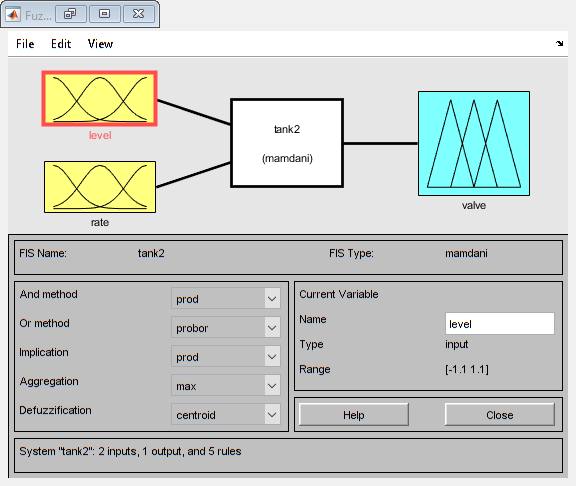

fuzzyLogicDesigner(tank)

Con apoyo de lo anterior, contesta lo siguiente:

**2.1** ¿Cuántas variables lingúistcas se tienen?

**Se tienen 3 variables, 2 variables de entrada llamadas "level" y "rate" y una de salida llamada "valve".**

**2.2** ¿Cuál es el universo de discurso de cada una?

**La variable "level" va de -1.1 a 1.1 .**

**La variable "rate" va de -0.35 a 0.35.**

**La variable "valve" va de -1 a 1.**

**2.3** Grafica las conjuntos difusos de cada variable lingüistica.

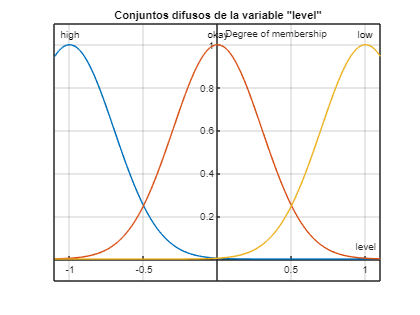

plotmf(tank,'input',1)
title('Conjuntos difusos de la variable "level"')
grid on
h=gca;
h.XAxisLocation="origin";
h.YAxisLocation="origin";

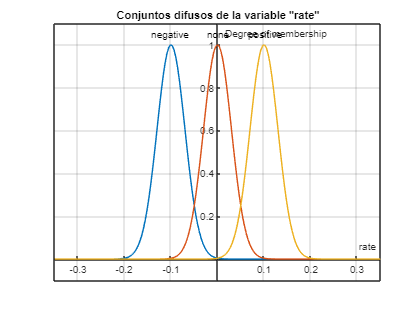

plotmf(tank,'input',2)
title('Conjuntos difusos de la variable "rate"')
grid on
h=gca;
h.XAxisLocation="origin";
h.YAxisLocation="origin";

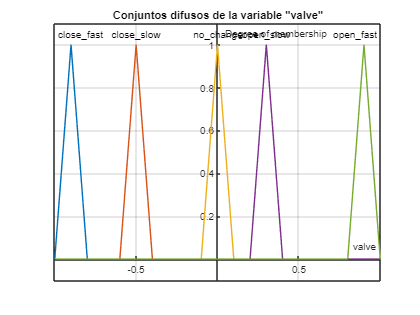

plotmf(tank,'output',1)
title('Conjuntos difusos de la variable "valve"')
grid on
h=gca;
h.XAxisLocation="origin";
h.YAxisLocation="origin";

**2.4** Muestra las reglas de inferencia difusa utilizadas.

**Las reglas uilizadas en este FIS son:**

**1.- Si el nivel esta bién, entonces la valvula no cambia**

**2.- Si el nivel esta bajo, entonces la valvula se abre rápido**

**3.- Si el nivel está alto, entonces la válvula se cierra rápido**

**4.- Si el nivel está bien y la tasa es positiva, entonces la vávula se cierra lento**

**5.- Si el nivel está bien y la tasa es negativa, entonces la vávula se abre lento**

**2.5** Explica en que consiste la implementación del sistema (una descripción general de todos bloques) en especial los bloque de visualización, así como la simulación mostrada.

**Nuestras entradas comienzan con un generador de señales que nos proporciona únicamente una señal de 0,5 con una frecuencia de 0,1 rad/s, a la que se le resta una constante de 1, dándonos una señal oscilante que va de 0,5 a 1,5. **

**Después de esto hay que pasar a nuestros 2 tipos de controladores, siendo el primero de estos en PID y posteriormente nuestro sistema de inferencia difusa, donde entrará el error la tasa de cambio del caudal y una vez aplicada la derivada a la salida del sistema arrojaría nuestro valor de cambio en la pendiente de este. **

**La salud obtenida será capaz de pasar de ahí a todo un sistema en el que podremos decidir si utilizar el PID OFES para poder controlar bajo el tanque y con una zona tiene la animación está demasiado llena mostraría la salida del sistema. En esta animación se mostrará el cambio de la señal de 1,5 a 0,5, teniendo en cuenta que si utilizamos el control PID de tienen errores en el tiempo de asentamiento y en el sobrellenado, mientras que si se utiliza el controlador FIS el cambio será un poco más suave debido al ajuste que se realiza en la apertura de la válvula, que en este caso amortigua el sistema.**

### Problema 3.

La logica difusa se puede implementar en varias aplicaciones en ingeniería, tal es el caso de:

**Hela Lassoued, Raouf Ketata**, *Chapter 5 - Genetic fuzzy logic based system for arrhythmia classification*, Editor(s): Olfa Boubaker, Control Theory in Biomedical Engineering, Academic Press, 2020, Pages 105-127, ISBN 9780128213506.

Contesta las siguentes preguntas respecto a la revisión del documento

**3.1** ¿Qué factores explican la presencia de arritmias?

**Hábitos alimenticios poco saludables, mucho estres, edad, antecedentes familiares, falta de actividad fisica y muchos otros.**

**3.2** ¿A qué se refieren las siglas DSS?

**Decision Support System (Sistema de soporte de decisiones)**

**3.3** ¿A qué se refieren las siglas FLC?

**Fuzzy Logic Controller (Controlador de lógica difusa)**

**3.4** ¿A qué se refieren las siglas GA?

**Genetic Algorithm (Algoritmo genético)**

**3.5** ¿Cuál es el principal objetivo del capítulo 5?

**Mejorar la precision de DSS basada en la clasificacion de arritmias cardiacas**

**3.6**  La base de datos  *MIT-BIH Arrhythmia Database* contine varios registros de distintos tipos de arritmias, ¿Cuáles son estos?

**Ritmo sinusal normal/Norma Sinus Rhythm (NSR), Contracción ventricular prematura/Premature Ventricular Contraction (PVC), Bloque de rama izquierda/Left Bundle Branch Block (LBBB), Bloqueo de rama derecha/Right Bundle Branch Block (RBBB) y Latidos estimulados/Paced Beats (P)**

**3.7** ¿De que depende el desempeño de un  FLC?

**Depende de los ajustes en los parámetros de las funciones de membresia y sus reglas**

**3.8** ¿Para que utilizan un GA?

**Se utiliza para ajuistar los parametros de membresia y los numeros de reglas del FLC. Ya que el sistema necesita definir el tupo correcto de arritmia para una muestra previamente desconocida.**

**3.9** La Figura 1 muestra un diagrama de bloques de la metodología implementada para la clasificación de arritmias. En nuestro caso nos interesa el bloque de clasificación. Este está compuesto por configuración y optimización. ¿En que consisten las entradas (input features) que recibe este bloque de clasificación? 

**Las entradas son las caracteristicas obtenidas de cada sujeto que nos podria indicar que tipo de arritmia podria tener como frecuencia cariaca, y la duracion entre cada intervalo de pulsación.**

**3.10** La principal ventaja de un FLC es que no es necesario un modelo matemático para la implementación del controlador (difuso). En general esto es el caso (como en el ejemplo del Problema 2), aunque puede suceder que para resolver cierta clase de problemas  sea necesario el modelo matemático de un subsistema. Se espera que la Figura 10 sea transparente en este momento. De acuerdo al texto ¿Cuál es la diferencia entre la inferencia de Mamdani y Sugeno?

**Para el mecanismo de inferencia de Mamdani, el antecedente y el consecuente son variables difusa; mientras que  para la inferencia Sugeno, el antecedente es una variable difusa, pero el consecuente es una constante o una funcion linear.**

**3.11** De la sección 2.2.1 FLC configuration, ¿Cuántas variables lingüisticas se tienen? ¿Que tipo de conjuntos difusos son los consecuentes? ¿Cuantas reglas si-entones se proponen? ¿Que sistemas de inferencia se utiliza?   ¿Qué operaciones se utilizan para la Conjunción, Disyunción e Implicación?

**Tenemos 18 Variable Lingüsiticas con  6 entradas: promedio de frecuencia cardiaca (E1), amplitud de onda (E2), la duracion de intervalo PR (E3), duracion compleja QRS (E4). duracion del intervalo (E5) y duracion del intervalo ST (E6). Con 3 conjuntos difusos Minimo (MIN), Medio (MOY) y Maximo (MAX).   **

**Se proponen un total de 5 reglas si-entonces**

**Los conjuntos consecuentes son los tipos de arritmia posibles manejados como singletons.**

**Para Conjunción se utiliza el Producto, para Disyunción utiliza Sum y para la Implicacion se usa Producto**

**3.12** Reporte el diagrama de flujo del GA utilizado.

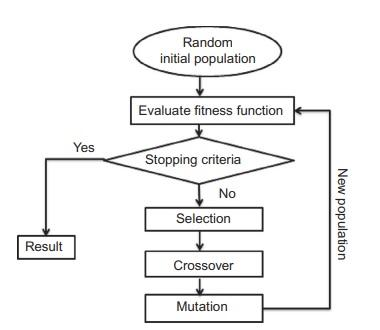

**3.13** Escriba la expresión matemática para la  *fitness function*  utilizada


$$\textrm{RMSE}=\sqrt{\frac{1}{N}\sum_{i=0}^N {\left(t_i -o_i \right)}^2 }$$


**3.14** No se pretende profundizar sobre el funcionamiento del GA. Basta con tener una visión general de su uso en esta implementación, En particular los parametros a optimizar se les da el nombre de *cromosomas. *En este caso ¿Qué representan los cromosomas? ¿Cuáles son los resultados del proceso de optimización?

**Los cromosomas representan los paramatros Gaussianos (**$\mu \;\;y\;\;\delta$**) y el número de reglas difusas.**

**A continuación se muestran la distribucion de los parametros de memebresia optimizados. **

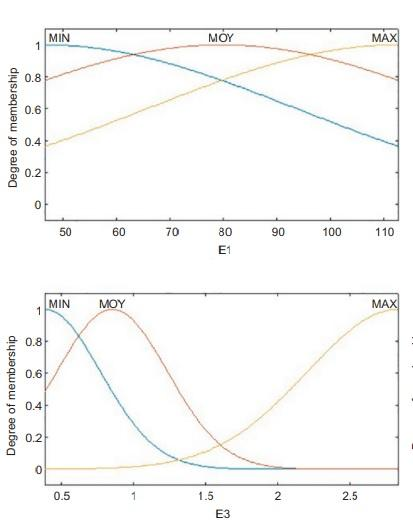 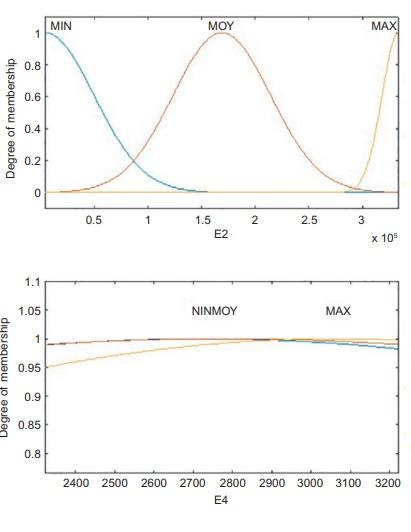 

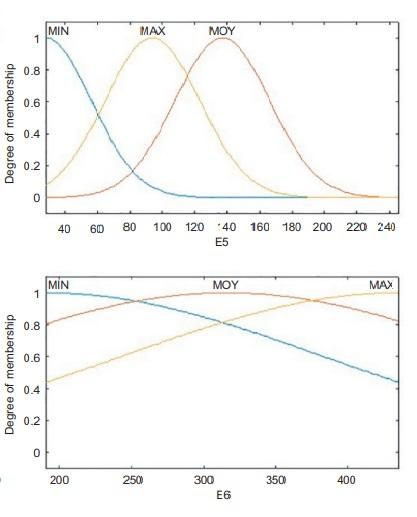

**3.15** ¿Cuáles fueron los resultados de la implementación?

**Para evaluar la eficacia de este proyecto, se realizaron comparaciones con trabajos relacionados anteriormente como se muestra en la siguiente tabla, donde se puede observar que todos los clasificadores anteriores tienen una efectividad de alrededor del 99.999% - 79.500%. Con lo que el FLC propuesto se considera un clasificador preciso y más interpretable que los clasificadores de redes neuronales.**